clear all, close all, clc

radio = 3;
r = 0;
imaginario = 0;
pasos = 1000;
dt = 1/pasos;
ruido = 0.1;
puntos = [-1 1i 1 -1+(1i/2) 1+(1i/2) ];
% [zc, zd] = circulo(radio, r, imaginario, pasos, ruido);
[zc, zd] = poligono(puntos, pasos, ruido);

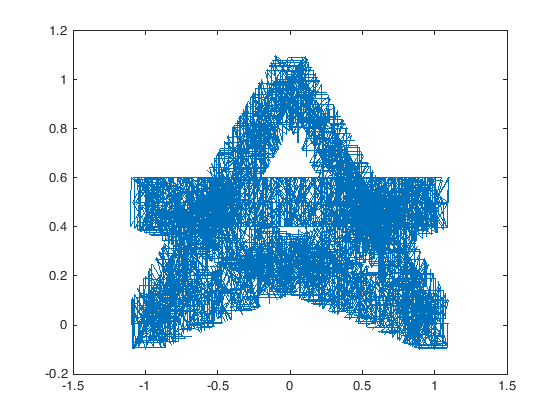

figure
% plot(real(zc), imag(zc))
% hold on
plot(real(zd), imag(zd))

% hold off

n = length(zd);
y = fft(zd,n);
fs = 1/dt;
f = (0:length(y)-1)*fs/length(y);
frec = abs(y);

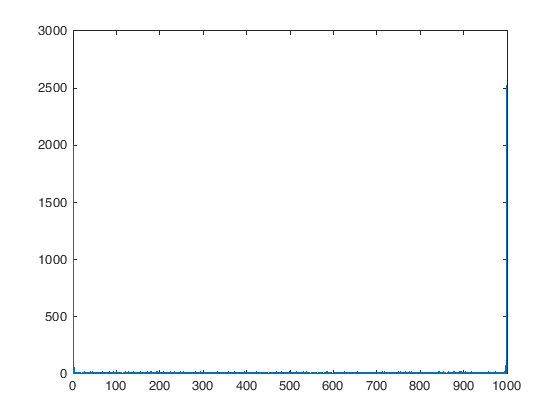

figure 
plot(f,frec)

#### Filter

ind = frec>50;
nfrec = frec.*ind;
zfill = ind.*y;
nzc = ifft(zfill);

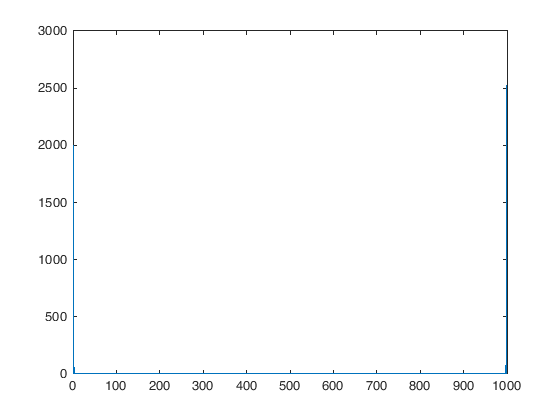

figure 
plot(f,nfrec)

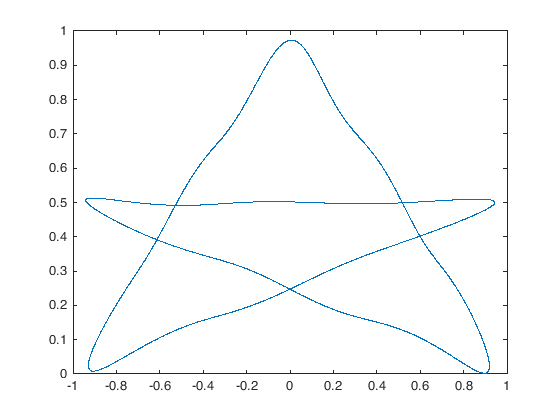

figure
plot(real(nzc),imag(nzc))